Lab 7

Event selection optimization You and your lab partner should pick *different* pT (transverse momentum) samples (one uses low-pT sampels and the other use high-pT samples) for this lab. In each pT sample, there are dedicated training samples for event selection optimization. All studies should be carried out by normalizing Higgs and QCD samples in each pT sample to given expected yields accordingly (See Dataset descriptions).

IM USING HIGH PT

h5disp("higgs_100000_pt_1000_1200.h5")

HDF5 higgs_100000_pt_1000_1200.h5 
Group '/' 
    Dataset 'higgs_100000_pt_1000_1200' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


h5disp("qcd_100000_pt_1000_1200.h5")

HDF5 qcd_100000_pt_1000_1200.h5 
Group '/' 
    Dataset 'qcd_100000_pt_1000_1200' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000



higgs = h5read("higgs_100000_pt_1000_1200.h5",'/higgs_100000_pt_1000_1200');
qcd = h5read("qcd_100000_pt_1000_1200.h5",'/qcd_100000_pt_1000_1200');

- Make a stacked histogram plot for the feature variable: mass (a regular histogram)

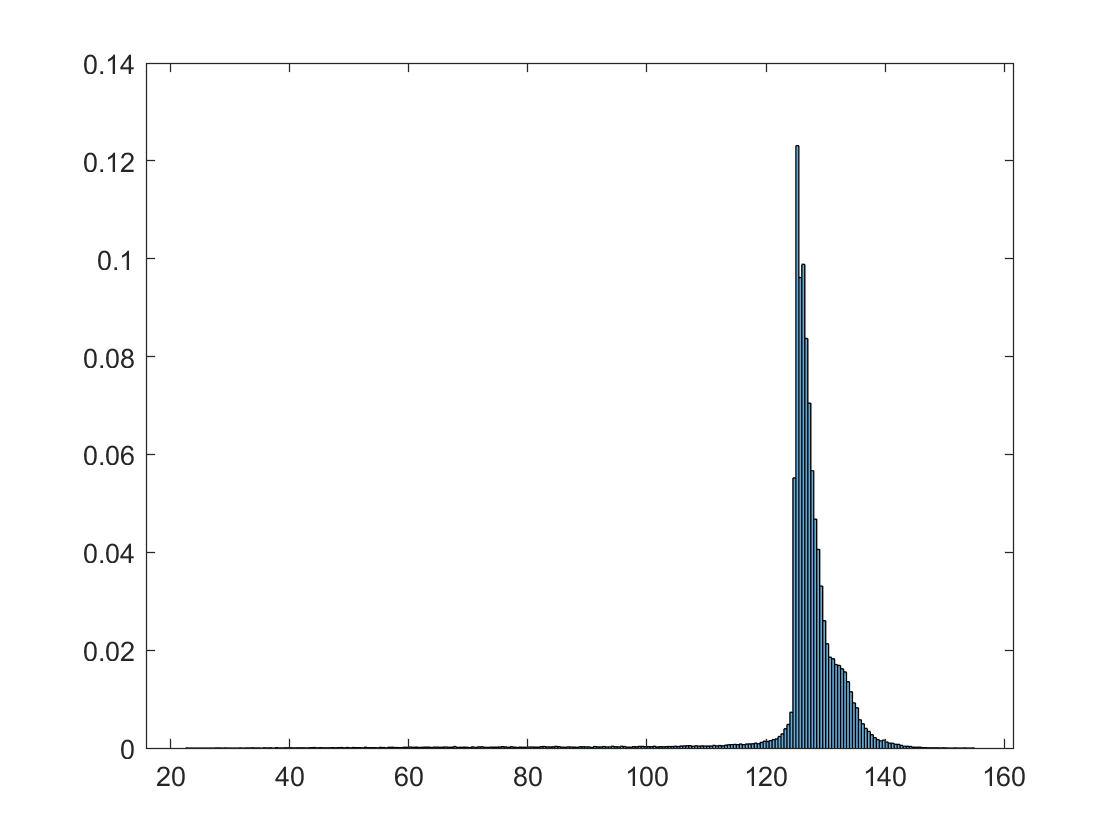

hh =   Histogram with properties:

             Data: [1×100000 double]
           Values: [1×265 double]
          NumBins: 265
         BinEdges: [1×266 double]
         BinWidth: 0.5000
        BinLimits: [22.5000 155]
    Normalization: 'probability'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


hh = histogram(higgs(4,:),'Normalization','probability');

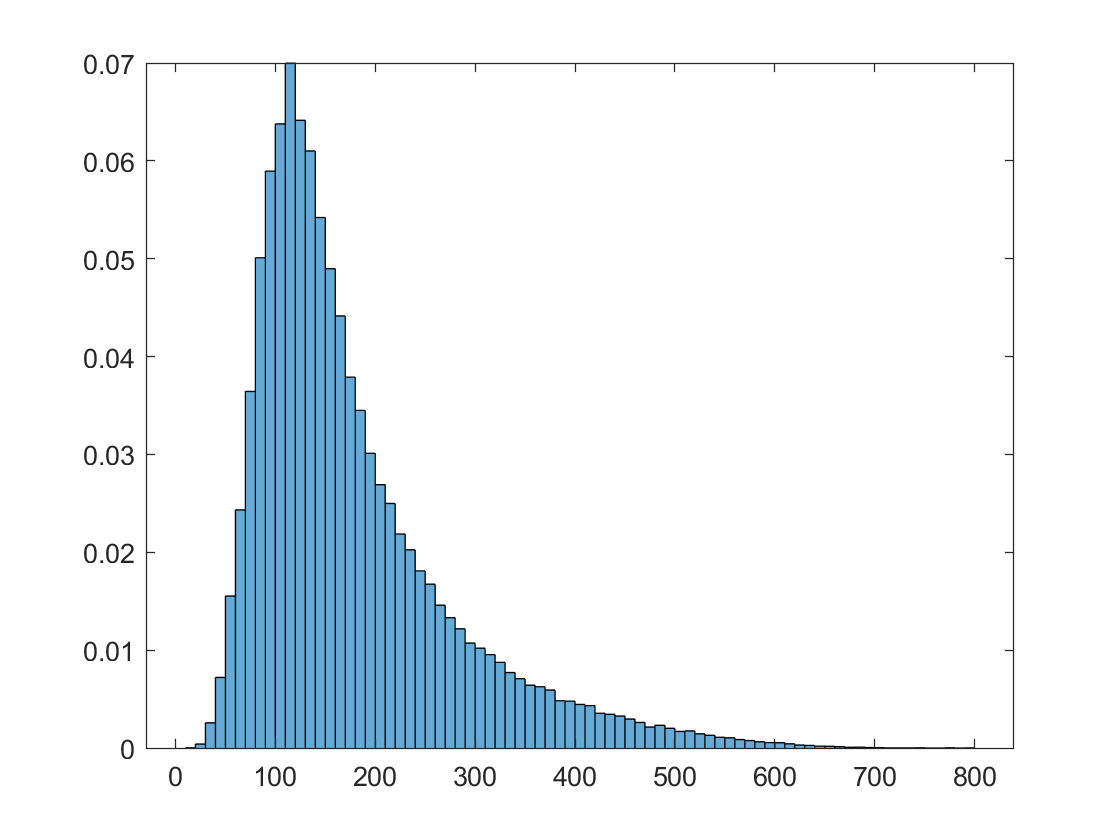

hq =   Histogram with properties:

             Data: [1×100000 double]
           Values: [1×79 double]
          NumBins: 79
         BinEdges: [1×80 double]
         BinWidth: 10
        BinLimits: [10 800]
    Normalization: 'probability'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


%%signal
hq = histogram(qcd(4,:),'Normalization','probability');

%%background
Nhiggs = 50;
Nqcd = 2000;

- Evaluate expected significance without any event selection.

- Use Poisson statistics for significance calculation

poiss = makedist('Poisson','lambda',2000);
signal = 2050;

pr = cdf(poiss,signal)

pr = 0.8704

sigma = norminv(pr)

sigma = 1.1282

- Compare your number of NHiggs/(√NQCD)NHiggs/(NQCD). If they are equivalent, explain your findings.

- --Number of events is a poisson distribution with lambda Nhiggs or Nqcd--

- significance of 2050 in a poisson 2000 dist

ratio = Nhiggs/(sqrt(Nqcd))

ratio = 1.1180

-- sigma??? :)

- Identify mass cuts to optimize the expected significance.

- Try different mass cuts systematically

- Evaluate expeced significance for each set of mass cuts

- Identify the set of the mass cuts which give you the highest significance.

my procedure 

- Make stacked histogram plots for the reset of features

- Set A of plots without any event selection

- Can you identify another feature as discriminative as mass feature (i.e. equal or better significance after feature cut)

- Set B of plots with your optimal mass cuts

- Can you identify additional feature to further imrpove expected signifiance?

- Optimize event selections using multiple features (if necessary)

- Find a set of feature cuts which can help you to achieve the best significance.

- Compare significance (before/after event selection) dervied in your pT samples to your lab partner. Describe your findings.

- Bonus (optional):

- Plot 2-dimensional scattering plots between top two most discriminative features

- Can you find a curve or a linear combination in this 2D plane which gives even better sensitivity? Extended reading: Lab 7 is a classificaition problem using multi-dimensional features in supervised machine learning. We can use popular machine learning tools to develop an optimial classifier which can maximize information by using all features. For interested students, you can read [https://scikit-learn.org/stable/supervised_learning.html](https://scikit-learn.org/stable/supervised_learning.html)